# **Outiers detection**

**----------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

On the basis of the majority voting method**, **we will apply first two methods for detecting outliers and then we will finally consider outliers just points classified by anomalous points by at least two of the algorithms implemented. These algorithms will be:

- Boxplot

- Local-Distance based outlier factor (LDOF)

- Local Outlier Factor

First, we put together all data

data10_Real = [data2010; data2011; data2012; data2013; data2014; data2015; data2016; data2017; data2018; data2019; dataRealTime]

## **Boxplot**

Before deleting outliers

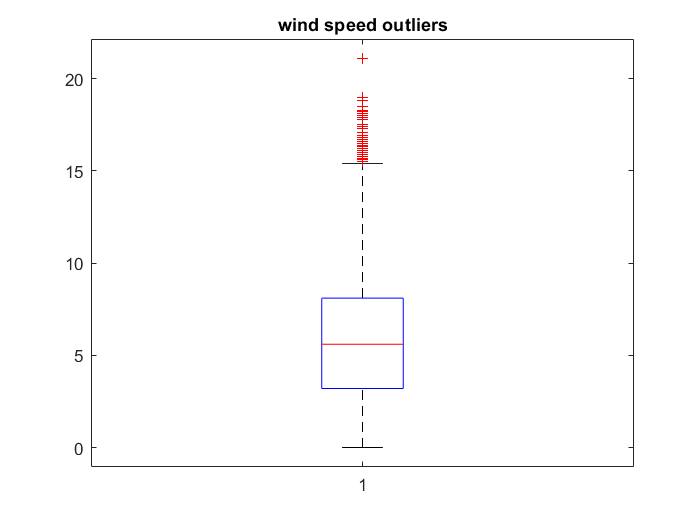

clf;
boxplot(data10_Real.WSPD) 
title('wind speed outliers')

idx1OutWSPD = isoutlier(data10_Real.WSPD, 'quartiles')

idx1OutWSPD = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


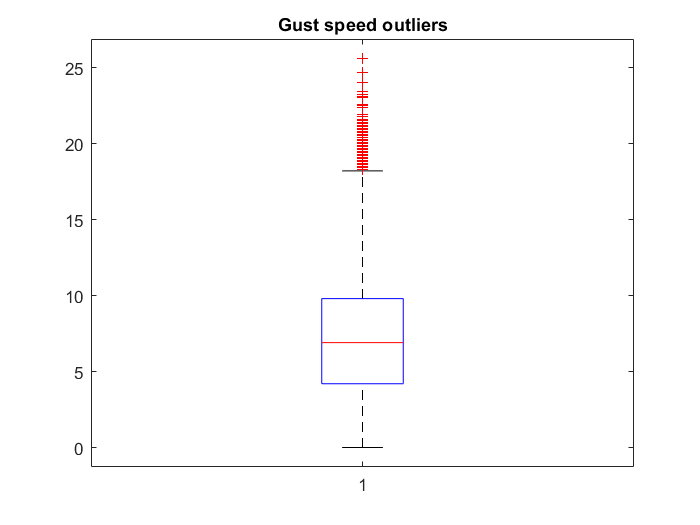

clf;
boxplot(data10_Real.GST)
title('Gust speed outliers')

idx1OutGST = isoutlier(data10_Real.GST, 'quartiles')

idx1OutGST = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


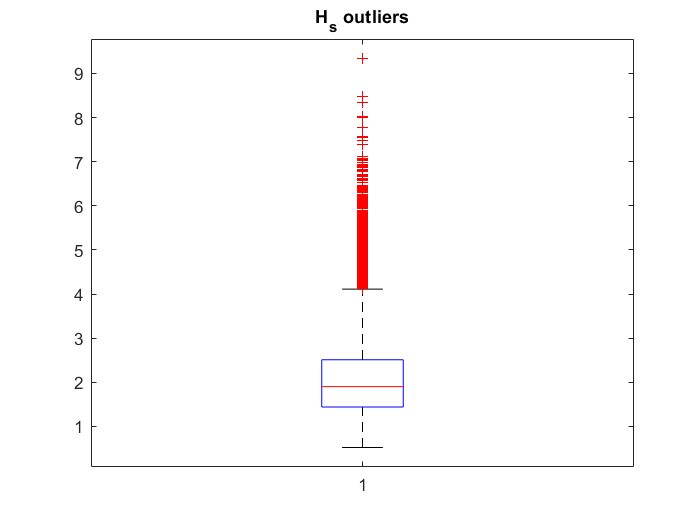

clf;
boxplot(data10_Real.WVHT)
title('H_{s} outliers')

idx1OutWVHT = isoutlier(data10_Real.WVHT)

idx1OutWVHT = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


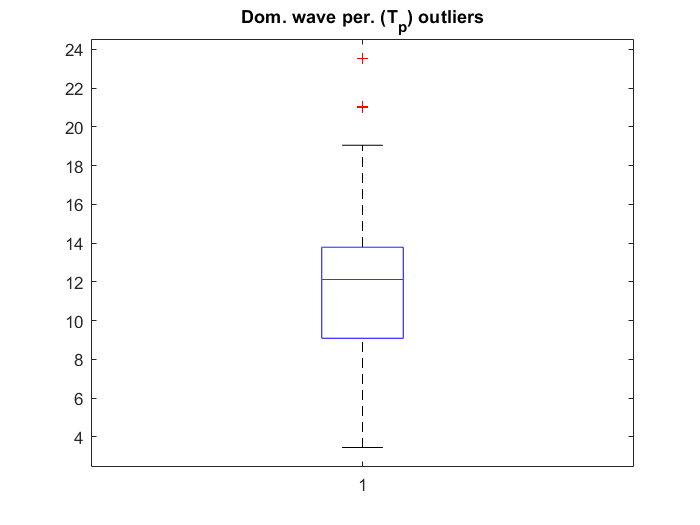

clf;
boxplot(data10_Real.DPD) 
title("Dom. wave per. (T_{p}) outliers")

idx1OutDPD = find_outliers(data10_Real.DPD)

idx1OutDPD = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


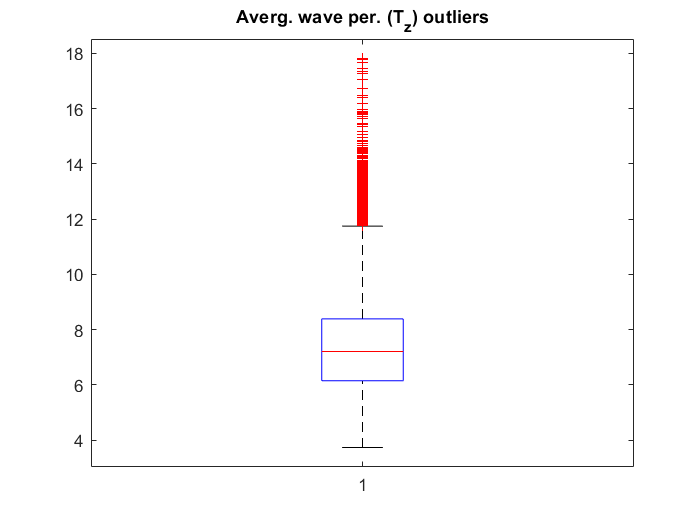

clf;
boxplot(data10_Real.APD)
title('Averg. wave per. (T_{z}) outliers')

idx1OutAPD = find_outliers(data10_Real.APD)

idx1OutAPD = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


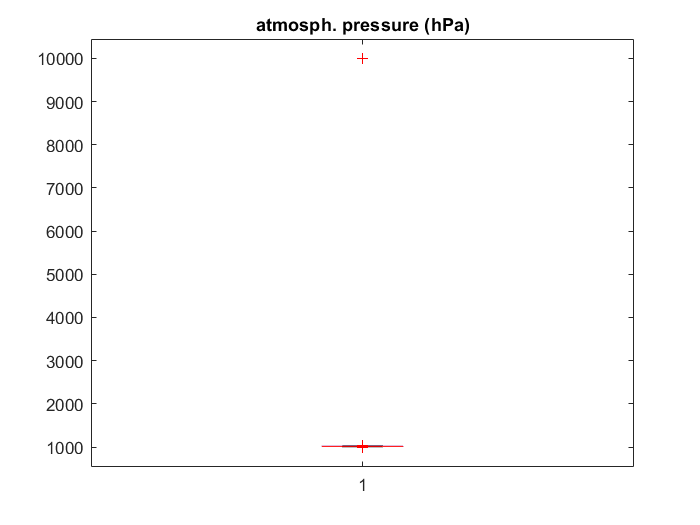

clf
boxplot(data10_Real.PRES)
title("atmosph. pressure (hPa)")

idx1OutPRES = find_outliers(data10_Real.PRES)

idx1OutPRES = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


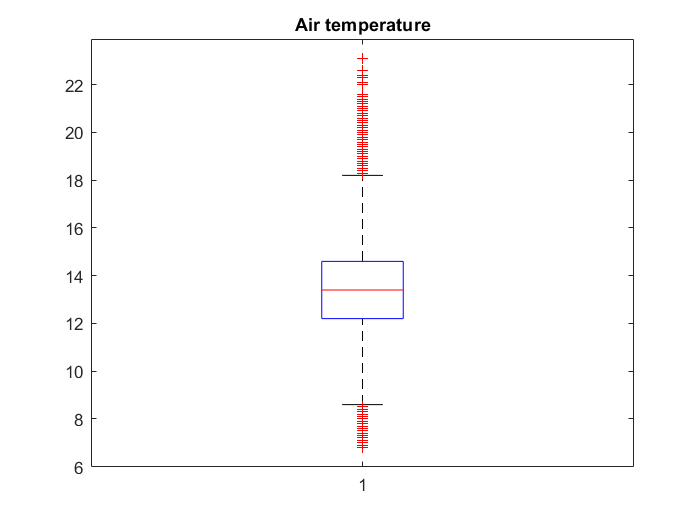

clf
boxplot(data10_Real.ATMP)
title('Air temperature')

idx1OutATMP = find_outliers(data10_Real.ATMP)

idx1OutATMP = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


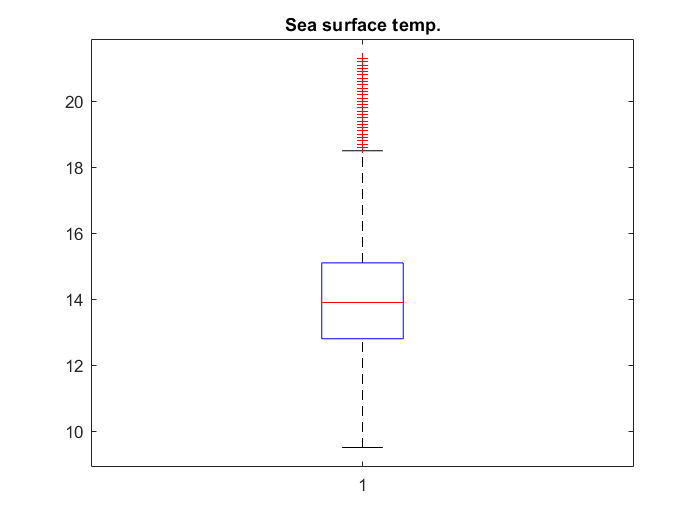

clf
boxplot(data10_Real.WTMP)
title("Sea surface temp.")

idx1OutWTMP = find_outliers(data10_Real.WTMP)

idx1OutWTMP = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


If we choose the complete data set for outliers detection, distribution measures from the station would be more realistic, because you aren't considering just one-year conditions, but you are taking points from several years and outliers would be anomaly points that don't occur almost any one of the years data.

## Local Distance-Based Outlier Factor  (LDOF)

Before applying this method

data10_Real = removevars(data10_Real, 'DATE');

[LDFO, D150,Idx150, KnnInnerDistance] = ldfo_outliers(table2array(data10_Real(:,{'WSPD','GST', 'WVHT','DPD', 'APD', 'PRES', 'ATMP','WTMP'})));

We have excluded Wind and Waves direction because they are circular variables. That means a value of 30º is the same as 30º + 360º

LDFO

The ideal threshold would be 1, but it is dependent from problem so we have decided stablish a threshold equals to the mean value of LDFO coefficients of points.

threshold = mean(LDFO) %1.6069

idxOutlierLDFO = (LDFO > (threshold))

threshold = 1.6069

numFilasLDFO = sum(idxOutlierLDFO)

idxOutlierLDFO = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


idxOutlierBP = idx1OutWSPD | idx1OutWTMP | idx1OutATMP |idx1OutPRES | idx1OutAPD...
    | idx1OutDPD | idx1OutWVHT | idx1OutGST

sum(idxOutlierBP)

idxOutlierBP = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


idxFinalOutlier = (idxOutlierBP == idxOutlierLDFO & idxOutlierBP == 1)

ans = 5369

sum(idxFinalOutlier)

We determine there are **1719** points with a high probability of being **outliers**, compared to 5330 detected by BoxPlot and 4820 detected by LDOF

## **Outliers deletion**

data10_Real(idxFinalOutlier,:) = []

idxFinalOutlier = 71031×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
